% clear variables in workspace and close all figures
clearvars; close all;

% reading
% reLoad= false; 
% if reLoad || ~exist('Data/SJELoadandWeatherData.mat', 'file')
%     
%     data = readtimetable('Data/SJE_LoadAndWeatherData.xlsx');
%     data = retime(data, 'hourly');
%     
%     save Data/SJELoadandWeatherData.mat data
% else
%     load Data/SJELoadandWeatherData.mat
% end

data = readtimetable('../Datasets/Ontario/TorontoIESO.xlsx');

% data(end,:) = []; % The last data is deleted because it only contains data from the first hour.


% Normalizing the variables
tmp = timetable2table(data);
tmp.DateTime = [];

maxdp = max(table2array(tmp));
mindp = min(table2array(tmp));

% y = (x - min) / (max - min)
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

ndata = data;
ndata.DemandKW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);        
 
clearvars -except data ndata mindp maxdp


% Inputs and Targets Creation
% There are 79 inputs for both forecasters consisting of:
% - 24 hourly load from the previous day
% - 24 hourly weather data from the previous day
% - 24 hourly weather parameters for the coming day
% - 7 day type indicator for each day of the week; refering to the coming day.
% The Load Forecaster predicts the 24 hrs output for the next day.
% 
% Inputs

% Inputs Creation
s=1;
p=buffer(ndata.DemandMW,24);
t=buffer(ndata.Temperature,24);
d = buffer(weekday(ndata.DateTime),24);
d = d(1, :);

N = length(d)-s;

dcode=zeros(7,N);

for i=1:size(dcode,2)

 dcode(d(i+s),i)=1;

end

inputs = [p(:,1:end-s); t(:,1:end-s);t(:,s+1:end);dcode]; % original

% Target variables
outputs = p(:,s+1:end);
% Network Inputs 
% Inputs are column vectors of 79 values containing previous day (24 hour) power demand, previous-day temperature, forecasted temperature for the nex day and type of day of the forecasted day

% Network outputs
% 
% Split the dataset to create a Training and Test set

train_test_boundary = ceil(.75 * size(inputs,2));

% index of train samples
trainInd = 1:train_test_boundary;

% input and outputs of the training set
trainX = inputs(:,trainInd);
trainblfY = outputs(:,trainInd);

% index of test samples
testInd = train_test_boundary+1:size(inputs,2);

testX = inputs(:,testInd);
testblfY = outputs(:,testInd);



% norm/denormalize functions
denorm = @(x,M,m)(x*(M-m)+m);
m =mindp(1); M= maxdp(1);

% dates
dt= buffer(datenum(ndata.DateTime),24);

traindt=(dt(:,trainInd));
testdt=(dt(:,testInd));


## plot training and test sets

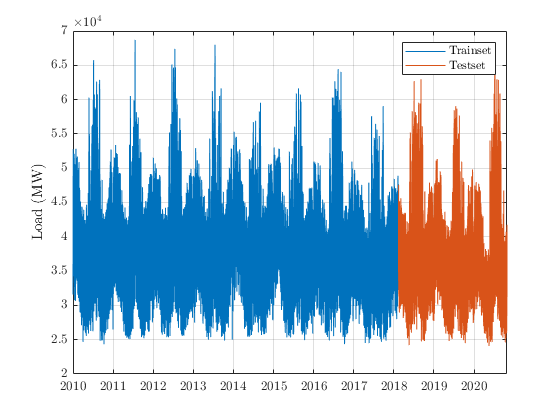


%%% plot results
FilNam='LoadForecastingSJE';
%figure;
set(groot,'DefaultTextInterpreter','LaTeX','DefaultAxesTickLabelInterpreter','LaTeX','DefaultLegendInterpreter','LaTeX')
FigScl=62/75; %Font downscale, roughly 8pt/10pt
FigWdt=4/FigScl; %Width
FigHgt=3/FigScl; %Height
%FigHgt=1.5*FigHgt%Test
Fig=0;
Fig=Fig+1;

figure;
t1 = datetime(datevec(traindt(:)));
plot(t1, denorm(trainblfY(:),M,m)/1000, 'DisplayName', 'Trainset');
hold on;
t1 = datetime(datevec(testdt(:)));
plot(t1, denorm(testblfY(:),M,m)/1000, 'DisplayName', 'Testset');
grid on;
ylabel('Load (MW)')
legend('show')


numResponses=24;
numFeatures=79;

filterSize=[6 5];
numFilters=15;

options = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ...
    'Verbose',false, ...
    'MaxEpochs',300,...
    'Shuffle','never', ...
    'Plots','training-progress'); % sgdm, 


layersCNN = ...
    [ imageInputLayer([numFeatures 1 1]) ... %before
    , convolution2dLayer(filterSize,numFilters,'Padding','same') ...
    , reluLayer ...    
    , maxPooling2dLayer([2 1]) ... %maxPooling2dLayer(2,'Stride',2)
    , fullyConnectedLayer(numResponses) ...
    , regressionLayer] % for 79 inputs

layersCNN =   1x6 Layer array with layers:

     1   ''   Image Input         79x1x1 images with 'zerocenter' normalization
     2   ''   Convolution         15 6x5 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                ReLU
     4   ''   Max Pooling         2x1 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected     24 fully connected layer
     6   ''   Regression Output   mean-squared-error

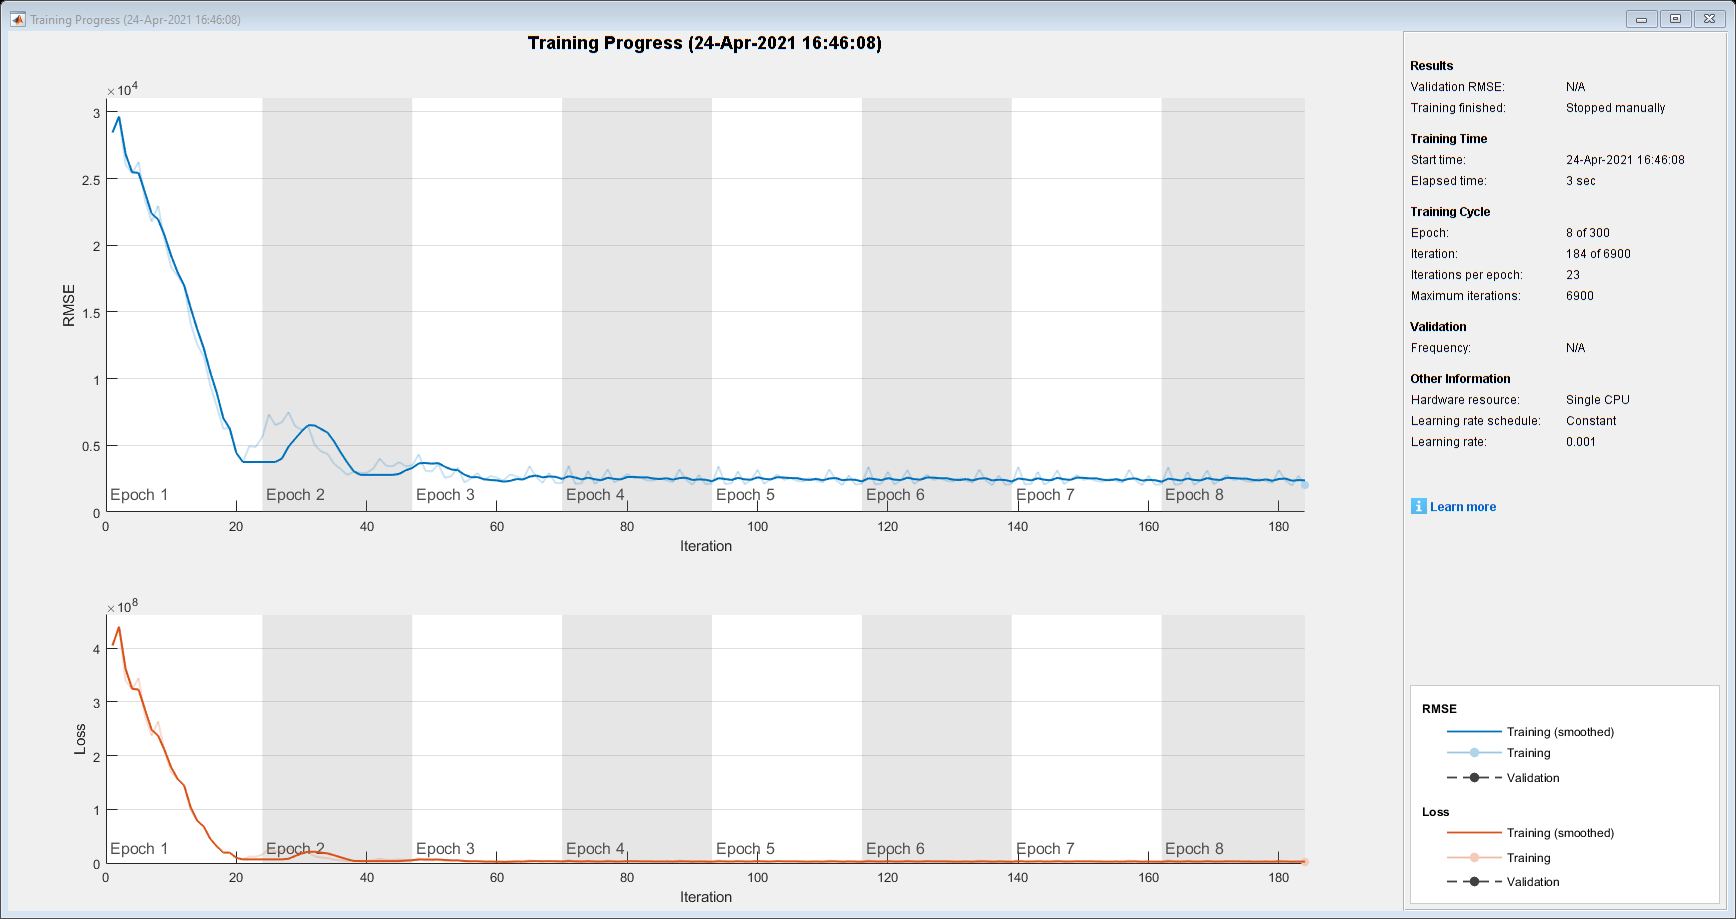




inputsCnn = [p(:,1:end-s); t(:,1:end-s);t(:,s+1:end);dcode]; % 
preshapedCnn=reshape(inputsCnn(:),numFeatures,1,1,size(inputsCnn,2));% This is done to convert inputs to 4D so Conv2D can 
% accept it (NumFeatures     1     1   NumbOfDays)


outputsCnn = outputs'; % before % outpusts should be NumdDays*NumbOfSamples


% Create training set

train_test_boundaryCnn = ceil(.75 * size(preshapedCnn,4));

% index of train samples
trainIndCnn = 1:train_test_boundaryCnn;

% input and outputs of the training set
trainXcnnf = preshapedCnn(:,:,:,trainIndCnn);
trainblfYf = outputsCnn(trainIndCnn,:);% before

% index of test samples
testIndCnn = train_test_boundaryCnn+1:size(preshapedCnn,4);

testXcnnf = preshapedCnn(:,:,:,testIndCnn);
testblfYcnnf = outputsCnn(testIndCnn,:);% before


netCnn = trainNetwork(trainXcnnf,trainblfYf,layersCNN,options);% layerscnn before


% CNN Network
YPredCnn = predict(netCnn,testXcnnf);
fCnn = denorm(YPredCnn, M,m);
fTestY = denorm(testblfYcnnf, M,m);

fTestY = fTestY';
fCnn = fCnn';

% dates
dtCnn= buffer(datenum(ndata.DateTime),24); 
traindtCnn=(dtCnn(:,trainIndCnn));
testdtCnn=(dtCnn(:,testIndCnn));
tCnn = datetime(datevec(testdtCnn(:)));


## errors from CNN network (each day is a column)


eCnn = fCnn-fTestY;
apeCnn = abs(eCnn)./fTestY; 
mapeCnn = mean(apeCnn)*100;
mean(mapeCnn)

ans = single
6.0570

## Plot forecasts (test set)

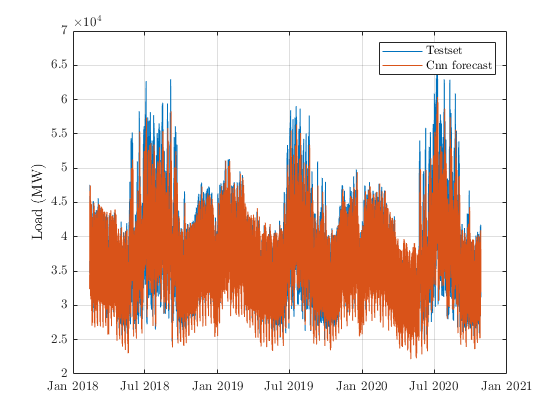


 
figure;
plot(tCnn,fTestY(:)/1000, 'DisplayName', 'Testset'), hold on
plot(tCnn,fCnn(:)/1000, 'DisplayName', 'Cnn forecast')
grid on;
ylabel('Load (MW)')
legend('show')

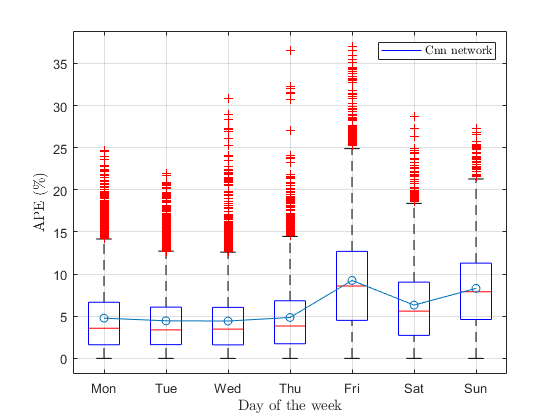


%% Boxplots 

[~,grp1]=weekday(tCnn);
figure;
Fig=Fig+1; 
boxplot(100*apeCnn(:), grp1);
mCnn=grpstats(apeCnn(:)*100,grp1);
hold on, plot(mCnn,'o-')
ylabel( 'APE ($\%$)')
xlabel( 'Day of the week')
grid on;
hLegend1 = legend(findall(gca,'Tag','Box'), {'Cnn network'});

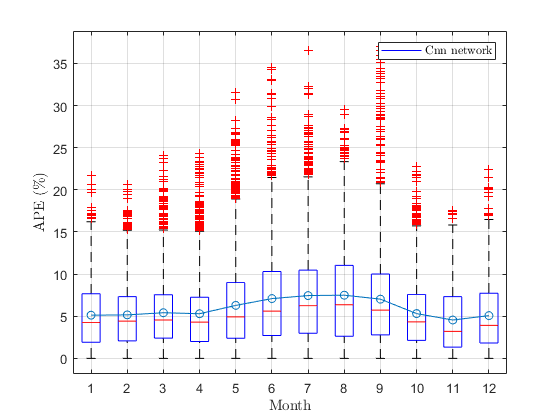


% Boxplots 
grp2=month(tCnn);
figure;
Fig=Fig+1; 
boxplot(100*apeCnn(:), grp2);
mCnn=grpstats(apeCnn(:)*100,grp2);
hold on, plot(mCnn,'o-')
ylabel( 'APE ($\%$)')
xlabel( 'Month')
grid on;
hLegend1 = legend(findall(gca,'Tag','Box'), {'Cnn network'});

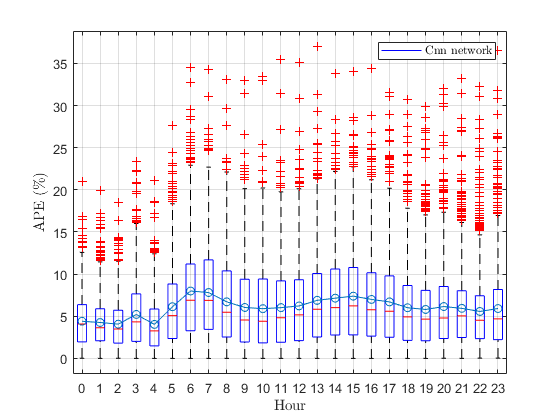


% Boxplots 
grp3=hour(tCnn);
figure;
Fig=Fig+1; 
boxplot(100*apeCnn(:), grp3);
mCnn=grpstats(apeCnn(:)*100,grp3);
hold on, plot(mCnn,'o-')
ylabel( 'APE ($\%$)')
xlabel( 'Hour')
grid on;
hLegend1 = legend(findall(gca,'Tag','Box'), {'Cnn network'});